datasetPath = fullfile('p_dataset_26');
imds = imageDatastore(datasetPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
[trainingSet, testSet] = splitEachLabel(imds, 0.75, 'random');
countEachLabel(trainingSet)

ans = 7×2 table
    Label    Count
    _____    _____

      0       191 
      4       191 
      7       191 
      8       191 
      A       191 
      D       191 
      H       191 


countEachLabel(testSet)

ans = 7×2 table
    Label    Count
    _____    _____

      0       63  
      4       63  
      7       63  
      8       63  
      A       63  
      D       63  
      H       63  


numTrainingImages = numel(trainingSet.Files);
numTestingImages = numel(testSet.Files);

disp(['Number of training images: ', num2str(numTrainingImages)]);

Number of training images: 1337


disp(['Number of validation images: ', num2str(numTestingImages)]);

Number of validation images: 441


img = readimage(trainingSet, 206);

% Extract HOG features and HOG visualization
[hog_2x2, vis2x2] = extractHOGFeatures(img,'CellSize',[2 2]);
[hog_4x4, vis4x4] = extractHOGFeatures(img,'CellSize',[4 4]);
[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);
% 
% % Show the original image
% figure; 
% subplot(2,3,1:3); imshow(img);
% 
% % Visualize the HOG features
% subplot(2,3,4);  
% plot(vis2x2); 
% title({'CellSize = [2 2]'; ['Length = ' num2str(length(hog_2x2))]});
% 
% subplot(2,3,5);
% plot(vis4x4); 
% title({'CellSize = [4 4]'; ['Length = ' num2str(length(hog_4x4))]});
% 
% subplot(2,3,6);
% plot(vis8x8); 
% title({'CellSize = [8 8]'; ['Length = ' num2str(length(hog_8x8))]});

cellSize = [4 4];
hogFeatureSize = length(hog_4x4);

% Loop over the trainingSet and extract HOG features from each image. A
% similar procedure will be used to extract features from the testSet.

numImages = numel(trainingSet.Files);
trainingFeatures = zeros(numImages,hogFeatureSize,'single');
% disp(size(trainingFeatures))
for i = 1:numImages
    img = readimage(trainingSet,i);
    
    img = im2gray(img);
    
    % Apply pre-processing steps
    img = imbinarize(img);
    disp(size(img))
    trainingFeatures(i, :) = extractHOGFeatures(img,'CellSize',cellSize);  
end

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128   128

   128


% Get labels for each image.
trainingLabels = trainingSet.Labels;

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
classifier = fitcecoc(trainingFeatures, trainingLabels);

% Extract HOG features from the test set. The procedure is similar to what
% was shown earlier and is encapsulated as a helper function for brevity.
[testFeatures, testLabels] = helperExtractHOGFeaturesFromImageSet(testSet, hogFeatureSize, cellSize);

% disp(size(testFeatures))
% Make class predictions using the test features.
predictedLabels = predict(classifier, testFeatures);

% Calculate validation accuracy
validation_accuracy = sum(predictedLabels == testSet.Labels) / numel(predictedLabels);

fprintf('Validation Accuracy: %.2f%%\n', validation_accuracy * 100);

Validation Accuracy: 99.09%



% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

helperDisplayConfusionMatrix(confMat)

char   | 0        4        7        8        A        D        H        
------------------------------------------------------------------------
0      | 0.97     0.00     0.00     0.03     0.00     0.00     0.00     
4      | 0.00     0.98     0.00     0.00     0.02     0.00     0.00     
7      | 0.00     0.00     1.00     0.00     0.00     0.00     0.00     
8      | 0.00     0.00     0.00     1.00     0.00     0.00     0.00     
A      | 0.00     0.00     0.00     0.00     1.00     0.00     0.00     
D      | 0.00     0.00     0.00     0.00     0.02     0.98     0.00     
H      | 0.00     0.00     0.00     0.00     0.00     0.00     1.00     


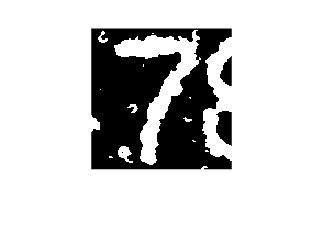

   128   128



Image width: 128


Image height: 128


Number of channels (color planes): 1


% Specify the file path of the BMP image you want to read
imageFilePath = ['./cropped_characters/character_5.png'];

% Read the BMP image
try
    test_img = imread(imageFilePath);
    
    % Display the image
    imshow(test_img);
    disp(size(test_img))
    % Optional: Get image size
    [height, width, numChannels] = size(test_img);
    disp(['Image width: ', num2str(width)]);
    disp(['Image height: ', num2str(height)]);
    disp(['Number of channels (color planes): ', num2str(numChannels)]);
    
catch
    % Handle any errors that may occur during reading
    disp('Error reading the image. Please check the file path or format.');
end


% test_img = im2gray(test_img);
 
% Apply pre-processing steps
% test_img = imbinarize(test_img);

% test_img = zeros(128,128,3);

test_features = zeros(1,hogFeatureSize,'single');

test_features(:,:) = extractHOGFeatures(test_img,'CellSize',cellSize);  

disp(size(test_features))

           1       34596



% plot(hogVisualization); 
% Make a prediction using the SVM model
predictedLabel = predict(classifier, test_features);

% Display the predicted label
fprintf('Predicted Label: %s\n', predictedLabel);

Predicted Label: H


% 
% fprintf('Test Accuracy: %.2f%%\n', test_accuracy * 100);

function helperDisplayConfusionMatrix(confMat)
    % Display the confusion matrix in a formatted table.
    
    % Convert confusion matrix into percentage form
    confMat = bsxfun(@rdivide,confMat,sum(confMat,2));
    
    digits = ['0','4','7','8','A','D','H'];
    colHeadings = arrayfun(@(x) x,digits,'UniformOutput',false);
    format = repmat('%-9s',1,11);
    header = sprintf(format,'char   |',colHeadings{:});
    fprintf('\n%s\n%s\n',header,repmat('-',size(header)));
    for idx = 1:numel(digits)
        fprintf('%-9s',   [digits(idx) '      |']);
        fprintf('%-9.2f', confMat(idx,:));
        fprintf('\n')
    end
end

function [features, setLabels] = helperExtractHOGFeaturesFromImageSet(imds, hogFeatureSize, cellSize)
    % Extract HOG features from an imageDatastore.
    
    setLabels = imds.Labels;
    numImages = numel(imds.Files);
    features  = zeros(numImages,hogFeatureSize,'single');

    % Process each image and extract features
    for j = 1:numImages
        img = readimage(imds,j);
        img = im2gray(img);
        
        % Apply pre-processing steps
        img = imbinarize(img);
        
        features(j, :) = extractHOGFeatures(img,'CellSize',cellSize);
    end
end
